# Forgetting Factor Recursive Least Squares

format long g;
clearvars, clc;

## Read Data

data = readmatrix('A1-007-OCV-25-20120905', 'Sheet', 'Sheet1');

## Initialization

time = data(:, 1);
current = -data(:, 2);
voltage = data(:, 3);
C_Ah = 1.1;

dt = [0; diff(time)];

## Calculate

Ah = cumsum(current .* dt) / 3600;
SOC = 1 - Ah / C_Ah;
SOC = max(0, min(1, SOC));

isRest = abs(current) < 0.05;
isDischarge = current > 0;
isCharge = current < 0;

% Data saat discharge dan rest
SOC_dis = SOC(isDischarge & isRest);
OCV_dis = voltage(isDischarge & isRest);

% Data saat charge dan rest
SOC_chg = SOC(isCharge & isRest);
OCV_chg = voltage(isCharge & isRest);

## Fit Polynomial

best_rmse_dis = inf;
best_order_dis = 0;
best_coeffs_dis = [];

best_rmse_chg = inf;
best_order_chg = 0;
best_coeffs_chg = [];

% Cari orde terbaik untuk discharge
for n = 2:12
    coeffs = polyfit(SOC_dis, OCV_dis, n);
    OCV_pred = polyval(coeffs, SOC_dis);
    rmse = sqrt(mean((OCV_pred - OCV_dis).^2));
    
    if rmse < best_rmse_dis
        best_rmse_dis = rmse;
        best_order_dis = n;
        best_coeffs_dis = coeffs;
    end
end


% Cari orde terbaik untuk charge
for n = 2:12
    coeffs = polyfit(SOC_chg, OCV_chg, n);
    OCV_pred = polyval(coeffs, SOC_chg);
    rmse = sqrt(mean((OCV_pred - OCV_chg).^2));
    
    if rmse < best_rmse_chg
        best_rmse_chg = rmse;
        best_order_chg = n;
        best_coeffs_chg = coeffs;
    end
end


fprintf('Best order for DISCHARGE: %d (RMSE = %.5f)\n', best_order_dis, best_rmse_dis);

Best order for DISCHARGE: 12 (RMSE = 0.01888)


disp(best_coeffs_dis);

  Columns 1 through 5

          -1446584.4162814          11163190.7589176         -38913665.8939828          80969230.8838528         -111925122.251515

  Columns 6 through 10

          108208185.078946          -74975713.885586          37490900.3041357         -13420608.2702279          3352772.91447966

  Columns 11 through 13

          -554757.62174768            54589.48705519         -2413.75162380002



fprintf('Best order for CHARGE:    %d (RMSE = %.5f)\n', best_order_chg, best_rmse_chg);

Best order for CHARGE:    12 (RMSE = 0.04234)


disp(best_coeffs_chg);

  Columns 1 through 5

          149825.235017915         -922768.922770081          2469998.18402416         -3726015.32445649          3389351.44138031

  Columns 6 through 10

         -1756369.51463559           284847.28911414           266649.93164858         -223245.360080603          83579.8245859655

  Columns 11 through 13

         -17852.4760289258          2107.28406151684          -104.15317183017



## Plotting Data

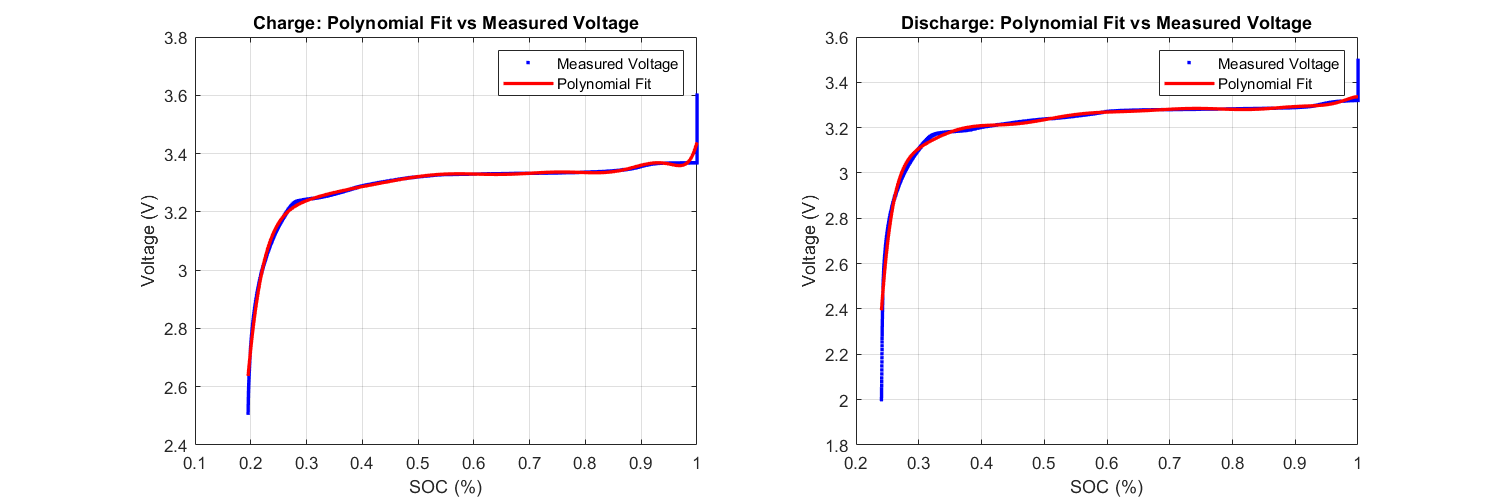

SOC_range_dis = linspace(min(SOC_dis), max(SOC_dis), 500);
OCV_fit_dis = polyval(best_coeffs_dis, SOC_range_dis);

SOC_range_chg = linspace(min(SOC_chg), max(SOC_chg), 500);
OCV_fit_chg = polyval(best_coeffs_chg, SOC_range_chg);

figure;
set(gcf, 'Position', [100, 100, 1200, 400]);

% Subplot untuk charging
subplot(1, 2, 1);
plot(SOC_chg, OCV_chg, 'b.', 'DisplayName', 'Measured Voltage');
hold on;
plot(SOC_range_chg, OCV_fit_chg, 'r-', 'LineWidth', 2, 'DisplayName', 'Polynomial Fit');
xlabel('SOC (%)');
ylabel('Voltage (V)');
title('Charge: Polynomial Fit vs Measured Voltage');
legend;
grid on;

% Subplot untuk discharging
subplot(1, 2, 2);
plot(SOC_dis, OCV_dis, 'b.', 'DisplayName', 'Measured Voltage');
hold on;
plot(SOC_range_dis, OCV_fit_dis, 'r-', 'LineWidth', 2, 'DisplayName', 'Polynomial Fit');
xlabel('SOC (%)');
ylabel('Voltage (V)');
title('Discharge: Polynomial Fit vs Measured Voltage');
legend;
grid on;

## Save The File

params = [best_coeffs_dis(:), best_coeffs_chg(:)];

fileID = fopen('_polynomialEstimate.txt','w');
fprintf(fileID, 'Discharge\tCharge\n');

if fileID < 0
    error('Gagal membuka file untuk ditulis.');
end

for i = 1:size(params,1)
    fprintf(fileID, '%.6f\t%.6f\n', params(i,1), params(i,2));
end

fclose(fileID);

disp(min(OCV_chg));

          2.50909280776978



disp(min(OCV_dis));

           1.9997239112854



disp(min(SOC_chg));

         0.195212825097076



disp(min(SOC_dis));

         0.240597374751389

